## GLEcustom_v13 Intro

This scrip is about to research about the meating time of two particular genetic locus. And in this scrip I will use a new kind of random force. In case of the unreliable result of v9 (1 dimension scrip), in this scrip we use 3 dimension. And i change the intensity of fbm.

And in order to expedite the scrip, i ignore part of the early history in GLE equation.

## v0 Intro

I try to adapt the v13 scrip, for there are several problems, for example, the distance when t=0, and delete the "ignored" function.

## v0test Intro

## Data Importing

import parameters

a1=[6.072747499083493E-9,0.5127045898796013,2.021229880364061E-8,0.6971394502383905];
m=a1(1);%just for test
psi=a1(2);%psi=0---> no potential
zeta=a1(3);
%H=a1(4);%not right H=0.5 when brownian motion.
H=0.5;
kB=1.3806505e-23;
T=293;
meeting_distance=5e-8;

import Time interval

delta=0.1;

import Total Time

Tmax=300;
imax=Tmax/delta;

import Total_experiment_number

Total_experiment_number=1000000;

import distribution intervals

distribution_interval=1;

## Random Force

We create the random force in this part and smooth it.

The interval of each point is delta

%BH=wfbm(H,imax+1);
%X=1:imax;
%x_length = linspace(1,Tmax);
%BHt=interp1(X,BH(2:imax+1),x_length,'pchip');%smooth the random
%plot(x_length,BHt)%draw the figure to verify

## Initialization

initialization v, x, and a data type

v=zeros(1,imax+1);
x=zeros(1,imax+1);
a=zeros(1,imax+1);
BH=zeros(1,imax+1);%may be imax+2 
first_passage_step=zeros(Total_experiment_number,1);

## Main loop

initialization v, x, and a when t =0

for n=1:Total_experiment_number
    k=1;
    v(k,1)=0;%should be random
    x(k,1)=1e-7;%should be random
    a(k,1)=0;%no need to be random
    BH(k,:)=(delta^H)*wfbm(H,imax+1);
    for i=1:imax
        KH=i:-1:1;
        k=1;
        x(k,i+1)=x(k,i)+v(k,i)*delta;
        v(k,i+1)=v(k,i)+a(k,i)*delta;
        a(k,i+1)=-zeta/m*v(k,i)+(2*zeta*kB*T)^0.5*(BH(k,i+1)-BH(k,i))/(m*delta);%ODE
        if x(1,i+1)*x(1,i)<0
            break
        end
    end

monitoring the progress rate

    progress_rate=n/Total_experiment_number*100;
    if i~=imax
        first_passage_step(n,1)=i;%means betwean t=(i-1)*delta adn t=i*delta
    end
    if progress_rate==floor(progress_rate)
        disp(['progress rate  ',num2str(progress_rate),' %'])
    end
end

progress rate  1 %
progress rate  2 %
progress rate  3 %
progress rate  4 %
progress rate  5 %
progress rate  6 %
progress rate  8 %
progress rate  9 %
progress rate  10 %
progress rate  11 %
progress rate  12 %
progress rate  13 %
progress rate  15 %
progress rate  16 %
progress rate  17 %
progress rate  18 %
progress rate  19 %
progress rate  20 %
progress rate  21 %
progress rate  22 %
progress rate  23 %
progress rate  24 %
progress rate  25 %
progress rate  26 %
progress rate  27 %
progress rate  30 %
progress rate  31 %
progress rate  32 %
progress rate  33 %
progress rate  34 %
progress rate  35 %
progress rate  36 %
progress rate  37 %
progress rate  38 %
progress rate  39 %
progress rate  40 %
progress rate  41 %
progress rate  42 %
progress rate  43 %
progress rate  44 %
progress rate  45 %
progress rate  46 %
progress rate  47 %
progress rate  48 %
progress rate  49 %
progress rate  50 %
progress rate  51 %
progress rate  52 %
progress rate  53 %
progress rate  54 %
progress

## Data output

FPT_distripution=zeros(floor(max(first_passage_step)*delta/distribution_interval),1);
max_n_interval=0;
for i=1:Total_experiment_number
    if floor(first_passage_step(i)*delta/distribution_interval)~=floor(max(first_passage_step)*delta/distribution_interval)
        FPT_distripution(floor(first_passage_step(i)*delta/distribution_interval)+1,1)=FPT_distripution(floor(first_passage_step(i)*delta/distribution_interval)+1,1)+1;
        if floor(first_passage_step(i)*delta/distribution_interval)+1>max_n_interval
            max_n_interval=floor(first_passage_step(i)*delta/distribution_interval)+1;
        end
    end
end

## Plotting and saving

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
save([storage_location,'\data\FPT','.m=',num2str(m),'.psi=',num2str(psi),'.zeta=',num2str(zeta),'.H=',num2str(H),'.d=',num2str(meeting_distance),'.N=',num2str(Total_experiment_number),'.mat'],"first_passage_step","FPT_distripution");

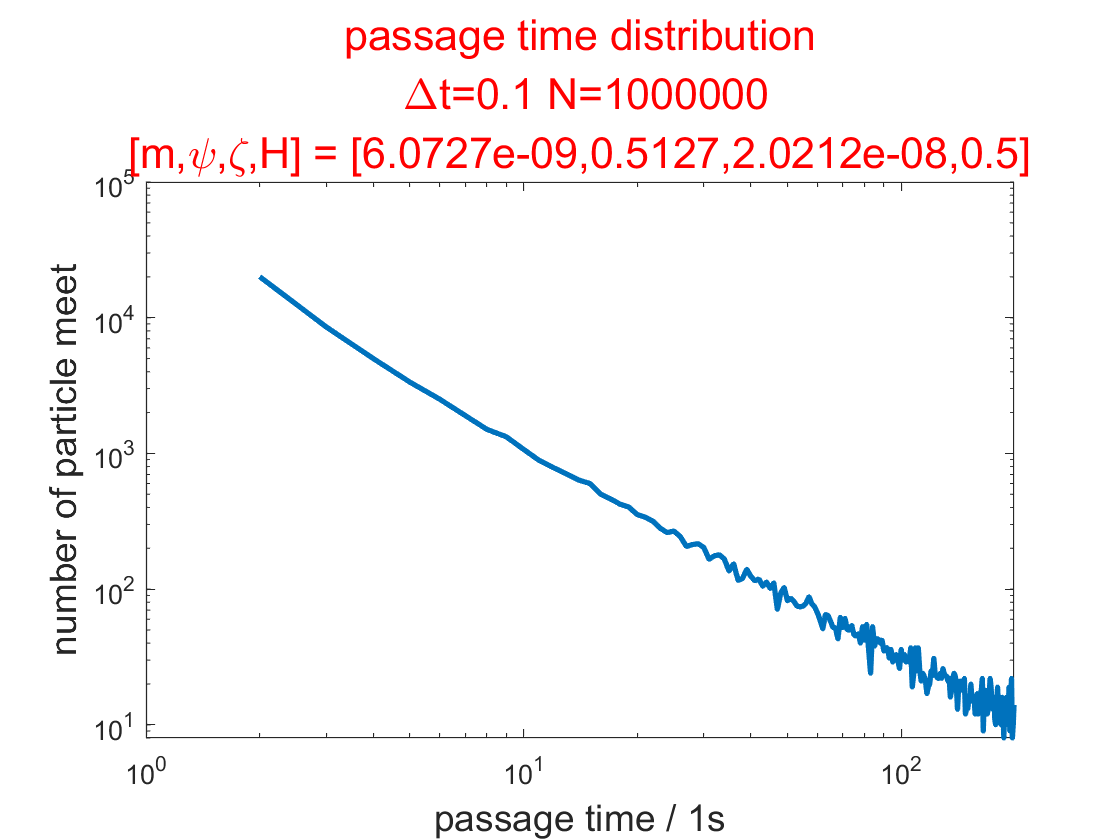

figure
max_n_interval=199;
plot(2:max_n_interval,FPT_distripution(2:max_n_interval,1),"LineWidth",2,"DisplayName",'GLE-sim FPT distribution');
set(gca,'yscale','log');
set(gca,'xscale','log');
xlabel(['passage time / ',num2str(distribution_interval),'s'],'FontSize',14);
ylabel('number of particle meet','FontSize',14);
title({'passage time distribution',[' \Deltat=',num2str(delta),' N=',num2str(Total_experiment_number)],['[m,\psi,\zeta,H] = [',num2str(m),',',num2str(psi),',',num2str(zeta),',',num2str(H),']']},'Color','r','FontSize',16)
saveas(gcf,[storage_location,'\image\FPT_distribution','.m=',num2str(m),'.psi=',num2str(psi),'.zeta=',num2str(zeta),'.H=',num2str(H),'.d=',num2str(meeting_distance),'.N=',num2str(Total_experiment_number),'.jpg']);
hold on

## Verifying

data_range=5:100;
log_t_scale=[];
t_scale=[];
log_testing_FPT=[];
fit_FPT=[];
for i=data_range
    log_t_scale=[log_t_scale,log(i*distribution_interval)];
    log_testing_FPT=[log_testing_FPT,log(FPT_distripution(i))];
end
k=polyfit(log_t_scale,log_testing_FPT,1);
log_fit_FPT=polyval(k,log_t_scale)

log_fit_FPT =     8.0395    7.7578    7.5197    7.3133    7.1314    6.9686    6.8213    6.6869    6.5632    6.4487    6.3421    6.2424    6.1487    6.0604    5.9768    5.8976    5.8222    5.7503    5.6816    5.6159    5.5528    5.4922    5.4339    5.3777    5.3235    5.2711    5.2204    5.1714    5.1238    5.0777    5.0329    4.9894    4.9471    4.9059    4.8657    4.8266    4.7885    4.7512    4.7149    4.6794    4.6446    4.6107    4.5774    4.5449    4.5131    4.4818    4.4512    4.4212    4.3918    4.3629


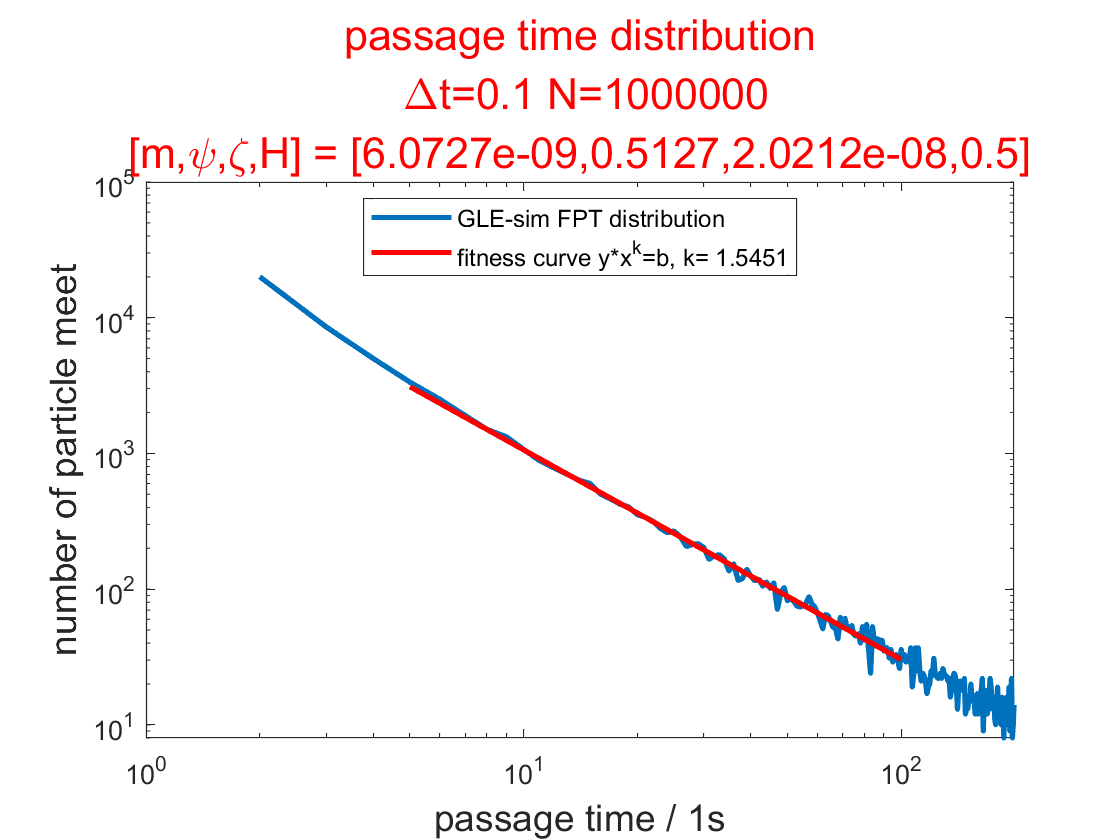

for i=1:length(log_t_scale)
    t_scale=[t_scale,exp(1)^(log_t_scale(i))];
    fit_FPT=[fit_FPT,exp(1)^(log_fit_FPT(i))];
end
plot(t_scale,fit_FPT,'r-','linewidth',2,'DisplayName',['fitness curve y*x^k=b, k= ',num2str(-k(1))])
legend("Location","best");